# Population analyses: Bayesian decoding, PCA and ICA

## 2.2. Identification of cell assemblies through independent component analysis

Cell assemblies represent clusters of neurons that synchronize their activity, potentially contributing to the brain's information processing. The identification of these cell assemblies has been facilitated by advanced techniques of dimensionality reduction such as Independent Component Analysis (ICA), which can reveal mixed patterns of coordinated firing.

These assemblies could serve as fundamental building blocks for encoding and consolidating memories, enabling the brain to efficiently represent spatial locations, routes, environmental cues and valence. Furthermore, cell assemblies might play a role in memory consolidation and recall to guide decisions based on past experiences.

In this tutorial, we will identify hippocampal cell assemblies in our dataset using ICA, enabling us to explore their functional properties by mapping the selectivity of their activation in response to external stimuli or behavioral variable. Independent Component Analysis (ICA) is a dimensionality reduction approach used to extract a meaningful subset of dimensions from large multivariate data ensembles. It is typically preceded by an initial dimensionality reduction step like Principal Component Analysis (PCA). Then it iteratively estimates the weights along each independent component to best capture correlations across dimensions within the PCA subspace. While both ICA and PCA aim at revealing underlying structures in the data, ICA differentiates itself by decomposing the data into statistically independent components, rather than orthogonal components (as in PCA). This type of approach not only unveils the hidden dynamics within neural ensembles but also provides a powerful tool to explore the potential functional roles of cell assemblies by converting an set of spikes from single cells into meaningful ensembles of coordinated firing patterns.

The analyses described in this section can be run by calling the following set of functions:

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = SetLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the spiking data into a matlab structure.
Spk = LoaddataSpk(loadparams, Nav.sampleTimes);

%define parameters for cell pattern detection
pattparams = SetPattParams(Nav,Spk.spikeTrain);

%Considering only pyramidal cells for cell assemblies detection
pattparams.cellidx = Spk.PyrCell;

%Identify cell assembly patterns through ICA
Pat = PatternAnalysis(Nav, Spk.spikeTrain, pattparams);

%Estimate Maps based on the vectors of activation of cell assemblies.
mapspattparams = SetMapsParams(Nav,Pat.activation);
PatMaps = MapsAnalysis(Nav, Pat.activation, mapspattparams);

### 3.2.1. Loading and preprocessing the behavioral and spiking data (as done in Tutorial1)

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = SetLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the spiking data into a matlab structure.
Spk = LoaddataSpk(loadparams, Nav.sampleTimes);

### 3.2.2 Parameters for cell assembly detection

Defining a set of parameters needed to detect cell assemblies through ICA. Such paramters are for instance the condition over which cell assemblies will be estimated or the time window over spike counts will be integrated to assess the projection of a particular set of spikes onto each of those assemblies.

%Experimental condition over which patterns will be estimated
pattparams.subset.Condition = [1 3 5];
pattparams.subset.Condition_op = 'ismember';

%lap type over which patterns will be estimated
pattparams.subset.XDir = [-1 1];
pattparams.subset.XDir_op = 'ismember';

%Minimum speed threshold over which patterns will be estimated
pattparams.subset.Spd =  2.5;
pattparams.subset.Spd_op = '>=';

%Subset of cells used for pattern detection. By default we'll use only 
%pyramidal cells since interneurons with high firing rates can bias the
%covariance matrix.
pattparams.cellidx = Spk.PyrCell;

%Minimal number of spikes over the train set to consider a cell for 
%pattern detection
pattparams.nspk_th = 0;

%Pattern activation threshold to convert activation strength into
%activation "spikes".
pattparams.strength_th = 5;

%Sampling rate of the data
pattparams.sampleRate = 1 / mean(diff(Nav.sampleTimes));

%Size of the spike count window in seconds
pattparams.timewin = .02;

This set of parameters can be obtained by calling SetPattParams**.m**

pattparams = SetPattParams(Nav,Spk.spikeTrain);
%Considering only pyramidal cells for cell assemblies detection
pattparams.cellidx = Spk.PyrCell;

### 3.2.3 Estimating cell assemblies from a subset of the data

We first define the time indices over which cell assemblies will be detected and select the cells that we will consider to identify assemblies.

%Time indices over which patterns will be detected
traintidx = true(size(Nav.sampleTimes));
pnames = fieldnames(pattparams.subset);
fnames = fieldnames(Nav);
for i = 1:numel(pnames)
    if ismember(pnames{i},fnames)
        fn = str2func(pattparams.subset.([pnames{i} '_op']));
        traintidx = traintidx & fn(Nav.(pnames{i}), pattparams.subset.(pnames{i}));
    elseif ~strcmp(pnames{i}(end-2:end),'_op')
        warning('some fields of pattparams.subset are not matching fields of Nav')
    end
end

%Selecting cell indices over which to detect assemblies
cellidx = find(pattparams.cellidx & sum(Spk.spikeTrain(traintidx,:), 1) > pattparams.nspk_th);

%Subsetting spikeTrain
spikeTrain = Spk.spikeTrain(:,cellidx);

%Number of cells
ncells = size(spikeTrain, 2);

The cell assembly detection is performed from the spikes integrated over a detection window. So we convert the spike trains into spike counts.

%Smoothing the spike train over the coincidence window to get spike counts
decbinwin = 2 * floor(0.5 * pattparams.timewin * pattparams.sampleRate) + 1;
if decbinwin > 1
    spkCount = zeros(size(spikeTrain));
    for icell = 1:ncells
        spkCount(:,icell) = smooth(spikeTrain(:,icell), decbinwin) * decbinwin;
    end
else
    spkCount = spikeTrain;
end

Before doing the independent component analysis, the dimensionality of the data is usually reduced by first performing a PCA and projecting the data onto a space defined by a subset of principal components that are sufficient to describe the data (according to some threshold).

Additionnally, to avoid that absolute firing rates bias our analysis, we will Z-score the spike counts over the train set.

%z-scoring spike counts
mu = mean(spkCount(traintidx,:), 1);
sd = std(spkCount(traintidx,:), 1);
Z = (spkCount(traintidx,:) - mu) ./ sd;

So Z is a ntime x ncells array of z-scored spike counts.

Plot the first 2 seconds of this array.

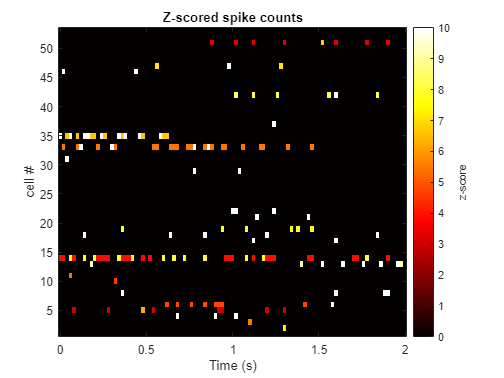

figure;

%Indices to plot
tidx = 0:1/pattparams.sampleRate:2;
idx = round(tidx * pattparams.sampleRate) + 1;

%Plotting Z
imagesc(tidx, [], Z(idx,:)');
set(gca,'Clim', [0 10], 'Ydir', 'normal');
colormap(hot);

%Labels, title, colorbar
xlabel('Time (s)');
ylabel('cell #');
title('Z-scored spike counts');
c = colorbar;
c.Label.String = 'z-score';

Principal Component Analysis (PCA) calculates orthogonal components, known as principal components, by finding the eigenvectors and eigenvalues of the data covariance matrix. The first principal component captures the maximum variance in the data, with subsequent components capturing decreasing orthogonal variance.

Compute the covariance matrix across neurons to estimate the principal components.

%number of time points
ntimepts = sum(traintidx);

%Covariance matrix
Corrmat = Z' * Z / ntimepts;

Plot the covariance matrix *Corrmat*

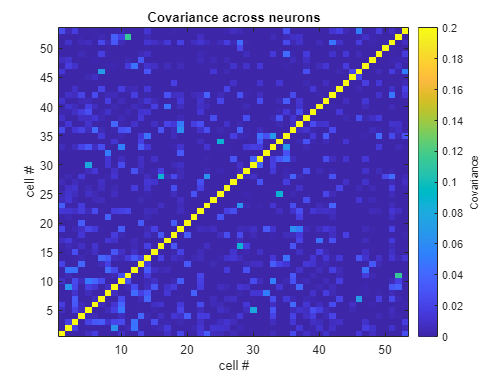

figure;

%Plotting Corrmat
imagesc(Corrmat);
set(gca, 'Clim', [0 0.2], 'Ydir', 'normal');
colormap(parula);

%Labels, title, colorbar
xlabel('cell #');
ylabel('cell #');
title('Covariance across neurons');
c = colorbar;
c.Label.String = 'Covariance';

Compute the principal components of the covariance matrix (i.e. its eigenvectors).

%Estimate the principal components and the diagonal matrix of eigen values
[P,D] = eig(Corrmat);

%Save the eigenvalues in a vector
eigval = diag(D);

P is a ncells x ncells array containing the unit-norm eigenvector coefficients in its columns.

Plot the first 2 principal components with the highest eigenvalues

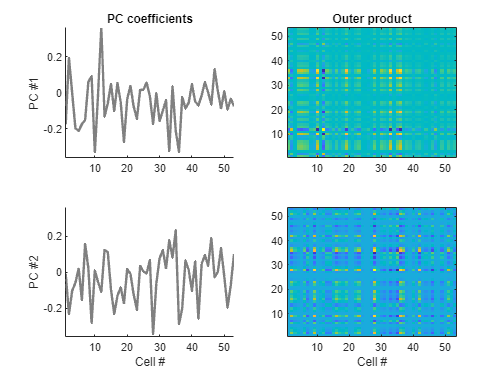

figure;

%number of PCs to plot
nPC = 2;

%max value for scaling purposes
m = max(P(:,(end-nPC+1):end), [], 'all');

%Plotting the PCs and their outer products
for i = 1:nPC
    %plotting the PC coefficients
    subplot(nPC, 2, (i-1)*2 + 1);
    plot(P(:,end-i+1), 'Color', [0.5 0.5 0.5],  'LineWidth', 2);
    set(gca, 'Xlim', [1 ncells], 'Ylim', [-m m], 'Box', 'off');
    ylabel(['PC #' num2str(i)])
    if i == nPC
        xlabel('Cell #')
    end
    if i == 1
        title('PC coefficients')
    end

    %Plotting the outer product of the PC
    subplot(nPC, 2, (i-1)*2 + 2);
    imagesc(P(:,end-i+1) * P(:,end-i+1)');
    set(gca, 'YDir', 'normal');
    if i == nPC
        xlabel('Cell #')
    end
    if i == 1
        title('Outer product')
    end
end

To reduce the dimensionality of the data, we select a subset of principal components that captures best the variance of the data. This is done by keeping only components whose eigenvalues are higher than expected, according to some theoretical threshold (defined by what's called the Marčenko-Pastur law) which states that for data whose elements are independent and identically distributed with zero mean and unit variance (which is our case since we z-scored the spike counts), all eigenvalues are bounded to the  interval [-(1 + ncells / ntimepts)^2 , (1 + ncells / ntimepts)^2].

So this means that principal components with eignenvalues higher than this range capture a significant amount of correlation in the data.

We will keep only those to reduce the dimensionality of the data before doing ICA.

%Threshold for selecting eigenvalues
eigval_th = (1 + ncells / ntimepts)^2;

%Keeping only the significant principal components
Psign = P(:,eigval > eigval_th);

In practice, the dimensionality reduction steps consists in projecting the z-scored spike counts onto the identified set of principal components.

%Projecting the data onto the selected principal components
Zproj = Z * Psign;

Plot the first 2 seconds of the spike counts projected on the PC subspace.

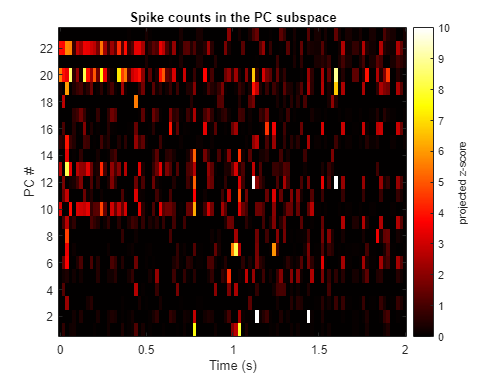

figure;

%Indices to plot
tidx = 0:1/pattparams.sampleRate:2;
idx = round(tidx * pattparams.sampleRate) + 1;

%Plotting Zproj
imagesc(tidx, [], Zproj(idx,:)');
set(gca,'Clim', [0 10], 'Ydir', 'normal');
colormap(hot);

%Labels, title, colorbar
xlabel('Time (s)');
ylabel('PC #');
title('Spike counts in the PC subspace');
c = colorbar;
c.Label.String = 'projected z-score';

We are now ready to perform the independent component analysis on the data projected on the PC subspace.

To do so, we will use the **fastICA** method (which fortunately, has already been coded by someone).

%Doing the ICA on the data projected onto the PCA subspace. W is the mixing
%matrix whose rows contain the weights to reconstruct each independent
%component from the original space.
Ncomp = size(Zproj, 2);
[~, W, ~, ~] = fastICA(Zproj', Ncomp, 'kurtosis', 0);

W is a Ncomp x Ncomp array containing the weights of the independent components in its rows.

Plot the first 2 components

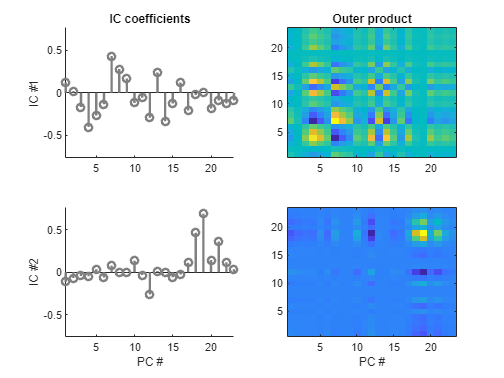

figure;

%number of ICs to plot
nIC = 2;

%max value for scaling purposes
m = max(W(1:nIC,:), [], 'all');

%Plotting the ICs and their outer products
for i = 1:nIC
    %plotting the IC coefficients
    subplot(nIC, 2, (i-1)*2 + 1);
    stem(W(i,:), 'Color', [0.5 0.5 0.5],  'LineWidth', 2);
    set(gca, 'Xlim', [1 Ncomp], 'Ylim', [-1.1*m 1.1*m], 'Box', 'off');
    ylabel(['IC #' num2str(i)])
    if i == nIC
        xlabel('PC #')
    end
    if i == 1
        title('IC coefficients')
    end

    %Plotting the outer product of the IC
    subplot(nIC, 2, (i-1)*2 + 2);
    imagesc(W(i,:)' * W(i,:));
    set(gca, 'YDir', 'normal');
    if i == nIC
        xlabel('PC #')
    end
    if i == 1
        title('Outer product')
    end
end

The identified independent compoennts are expressed in the PC subspace. What we actually want to know is which neurons are part of an assembly. So ultimately, we need to re-express these components in the original space of the recorded cells, by applying the transform matrix to the principal components

%Expressing the independent components in the original space, ie with a
%weight for each neuron describing its contribution to the corresponding
%component
Vpatt = Psign * W';

%Scaling the weights in Vpatt to unit norm. They should already be but
%thats just to be on the safe side.
Vpatt = Vpatt ./ sqrt(sum(Vpatt.^2, 1));

%By convention, enforcing that the largest element of each vector has a
%positive sign.
[p, d] = size(Vpatt);
[~, maxind] = max(abs(Vpatt), [], 1);
colsign = sign(Vpatt(maxind + (0:p:(d-1)*p)));
Vpatt = bsxfun(@times, Vpatt, colsign);

We can use the following measure to estimate the sparsity of each assembly pattern, i.e. the tendency for a pattern to be dominated by a small group of neurons. PSparsity = 1 if only one neuron contributes to the pattern's weights; it equals 0 if all neurons contribute equally.

%Computing the sparsity of each assembly pattern.
PSparity = ((sqrt(ncells) - sum(abs(Vpatt), 1)) ./ (sqrt(ncells) - 1));

Reorder the patterns according to their sparsity from highest to lowest.

[PSparity, idx] = sort(PSparity, 'descend');
Vpatt = Vpatt(:,idx);

Vpatt is a ncells x nComp array providing the contribution of cells for each independent component in its columns.

Plot the first and the last cell assembly patterns.

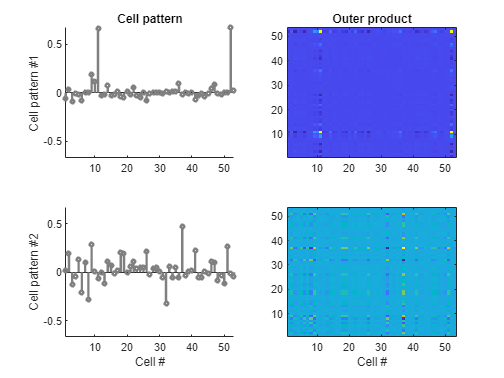

figure;

%indices of patterns to plot
patidx = [1 size(Vpatt,2)];
nPat = numel(patidx);

%max value for scaling purposes
m = max(Vpatt(:,patidx), [], 'all');

%Plotting the patterns and their outer products
for i = 1:numel(patidx)
    %plotting the pattern coefficients
    subplot(nPat, 2, (i-1)*2 + 1);
    stem(Vpatt(:,patidx(i)), 'Color', [0.5 0.5 0.5],  'LineWidth', 2, 'MarkerSize', 3);
    set(gca, 'Xlim', [1 ncells], 'Ylim', [-m m], 'Box', 'off');
    ylabel(['Cell pattern #' num2str(i)])
    if i == nPC
        xlabel('Cell #')
    end
    if i == 1
        title('Cell pattern')
    end

    %Plotting the outer product of the cell pattern
    subplot(nPat, 2, (i-1)*2 + 2);
    imagesc(Vpatt(:,patidx(i)) * Vpatt(:,patidx(i))');
    set(gca, 'YDir', 'normal');
    if i == nPat
        xlabel('Cell #')
    end
    if i == 1
        title('Outer product')
    end
end

For visualization purposes, we can identify neurons that are dominantly contributing to each identified pattern by detecting weights that exceed the mean weight across neurons by  2 s.d.

%Identifying cell assemblies within each pattern, i.e. cells that
%majoritarily contribute to the pattern
m = mean(Vpatt, 1);
s = std(Vpatt, 1);
cellAss = Vpatt > m + 2 * s;

We can plot those cell assemblies to see what they look like

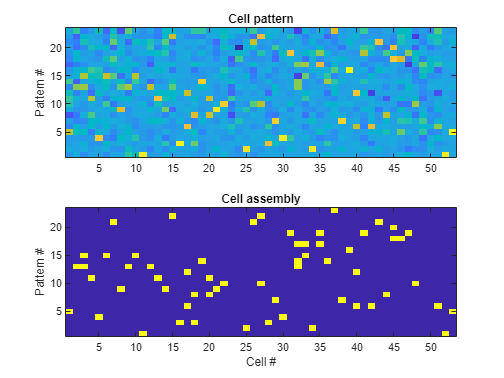

figure;

%Plotting the cell patterns
subplot(2,1,1);
imagesc(Vpatt');
set(gca,'YDir','normal')
ylabel('Pattern #');
title('Cell pattern')

%Plotting those assemblies
subplot(2,1,2);
imagesc(cellAss');
set(gca,'YDir','normal')
xlabel('Cell #')
ylabel('Pattern #');
title('Cell assembly')

### 3.2.4 Strength and activation of cell assemblies

Now that we have identified cell patterns, we can project the spike counts onto each of these components to measure their strength throughout the recording.

We'll first start by pre-processing again the entire spike train to obtain smoothed, z-scored spike counts.

%First smoothing the zscored spike trains by a Gaussian window having the 
%same s.d. as a square time window (??)
Zall = spikeTrain;
smthNbins = (pattparams.timewin * pattparams.sampleRate) / sqrt(12);
Zall = GaussianSmooth(Zall, [smthNbins 0]);

%z-scoring the smoothed spiketrains
mu = mean(Zall, 1);
sd = std(Zall, 1);
Zall = (Zall - mu) ./ sd;

Zall is a ntimes x ncells array of z-scored spike counts.

The strength of a given cell pattern can be obtained by projecting Zall onto it for each time t. However, we don't want the activation strength of a pattern to reflect the spike of a single cell contributing to that pattern; we want this measure to reflect co-activations between neurons. So we'll use a projection that is trickier than a simple dot product.

npatt = size(Vpatt, 2);

%Initilizing the pattern response array
pattResp = NaN(size(Zall, 1), npatt);

%Project spike counts onto each pattern
for k = 1:npatt
    %outer product of pattern k
    Pk = Vpatt(:,k) * Vpatt(:,k)';

    %removing diagonal elements of Pk to discard contributions from a
    %single neuron
    Pk(eye(size(Pk))>0) = 0;

    %computing the expression strength of pattern k as Zall(t,:) * Pk *
    %Zall(t,:)' for each t.
    Ztemp = Zall * Pk;
    pattResp(:,k) = sum(Ztemp .* Zall, 2);
end

Plot the first 2 seconds of the response stregth all cell patterns.

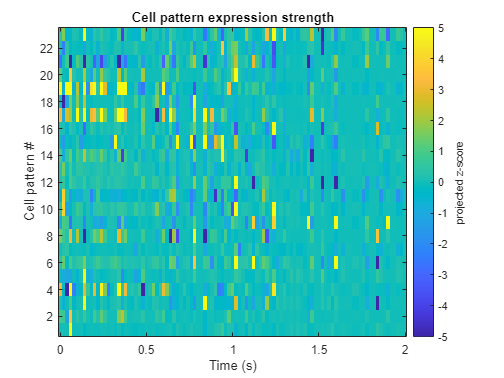

figure;

%Indices to plot
tidx = 0:1/pattparams.sampleRate:2;
idx = round(tidx * pattparams.sampleRate) + 1;

%Plotting Zproj
imagesc(tidx, [], pattResp(idx,:)');
set(gca,'Clim', [-5 5], 'Ydir', 'normal');
colormap(parula);

%Labels, title, colorbar
xlabel('Time (s)');
ylabel('Cell pattern #');
title('Cell pattern expression strength');
c = colorbar;
c.Label.String = 'projected z-score';

For each pattern, detect the peaks exceeding a z-score threshold (pattparams.strength_th). This will convert the expression strengths into a series of event.

%Detecting events of activation of each pattern when the projected z-score 
%value exceed a certain threshold.

%Initilizing the pattern response array
pattSpike = zeros(size(Zall, 1), npatt);

%Detect threshold crossing and find maxima
for k = 1:npatt
    binary = double(pattResp(:,k) > pattparams.strength_th);
    [~,loc] = findpeaks(pattResp(:,k) .* binary);
    pattSpike(loc,k) = 1;
end

Plot the first 2 seconds of the pattern activations

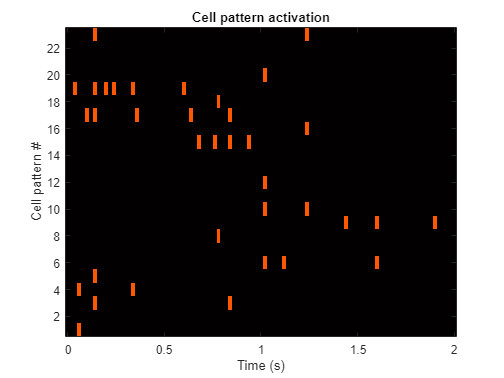

figure;

%Indices to plot
tidx = 0:1/pattparams.sampleRate:2;
idx = round(tidx * pattparams.sampleRate) + 1;

%Plotting Zproj
imagesc(tidx, [], pattSpike(idx,:)');
set(gca,'Clim', [0 2], 'Ydir', 'normal');
colormap(hot);

%Labels, title, colorbar
xlabel('Time (s)');
ylabel('Cell pattern #');
title('Cell pattern activation');

The entire analysis can be run by calling PatternAnalysis.m

pattparams = SetPattParams(Nav,Spk.spikeTrain);
%Considering only pyramidal cells for cell assemblies detection
pattparams.cellidx = Spk.PyrCell;
Pat = PatternAnalysis(Nav, Spk.spikeTrain, pattparams);

### 3.1.4 Mapping place fields of cell assemblies

Compute the spatial tuning of each assembly pattern from its activation events using the pre-run, run and post run conditions. To do that we can simply pass on the matrix of activation to activation (see Tutorial 2.1) after adjusting the parameters used for place field analysis (in particular by making sure that the list of cell to select matches the number of assembly patterns).

pattmapsparams = SetMapsParams(Nav,Pat.activation);
PattMaps = MapsAnalysis(Nav, Pat.activation, pattmapsparams);

Plot the place fields of all cells assemblies for left to right and right to left directions.

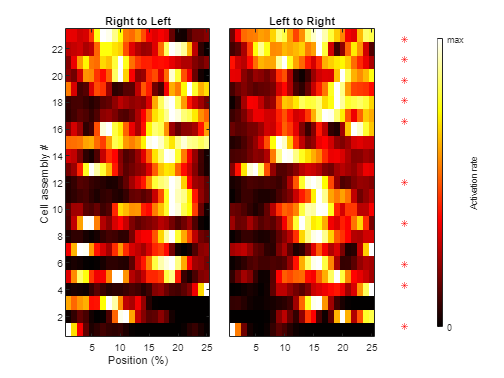

figure;

%for titling
dirnames = {'Right to Left','Left to Right'};

%Plotting place fields of cell assemblies, normalized to max
%activation rate
for idir = 1:2
    subplot(1,5,(idir-1)*2 + 1:idir*2);
    imagesc(squeeze(PattMaps.map(:,idir,:) ./ max(PattMaps.map(:,idir,:), [], 3)));
    set(gca,'Clim', [0 1], 'Ydir', 'normal');
    title(dirnames{idir})
    if idir == 1
        xlabel('Position (%)')
        ylabel('Cell assembly #')
    end
    if idir == 2
        set(gca, 'Ytick', []);
    end
end
colormap(hot);

%Marking with an asterisk those with a significant place field.
subplot(1,10,9);
sigidx = find(PattMaps.LLH_pval <= 0.05);
plot(zeros(size(sigidx)), sigidx - 0.5, 'r*');
set(gca, 'Xtick', [], 'XColor', 'none', 'Ytick', [], 'YColor', 'none')

%Colorbar
subplot(1,10,10);
set(gca,'Visible', 'off')
c = colorbar('Location', 'west', 'Ticks', [0 1], 'TickLabels', {'0', 'max'});
c.Label.String = 'Activation rate';

Similarly, we can run the decoding analysis on these cell pattern activations

pattdecparams = SetDecParams(Nav,Pat.activation);
PatDec = DecodingAnalysis(Nav, Pat.activation, pattdecparams);

Calculate the distribution of positions decoded from the pattern activations, as a function of actual positions, using the data on which the decoder has been trained.

%time indices to consider
valididx = PatDec.decparams.traintidx & ~isnan(PatDec.XDecMax) & ~isnan(PatDec.X);

%Calculating the distribution of decoded positions as a function of the
%actual positions
Xdecmat = ComputeMap(PatDec.X(valididx), PatDec.XDecMax(valididx), ones(size(PatDec.X(valididx))), PatDec.nXbins, PatDec.nXbins);

%Smoothing the distribution across decoded position (but not across
%actual positions).
Xdecmat = GaussianSmooth(Xdecmat, [1 0]);

%Expressing the distribution as a probability density, i.e. normalizing
%so that everything sums to one for each actual position bin.
Xdecmat = Xdecmat ./ sum(Xdecmat, 1);

%Normalizing this confusion matrix by the chance level, i.e. 1 / PatDec.nXbins.
Xdecmat = Xdecmat / (1/PatDec.nXbins);


Plot the confusion matrix.

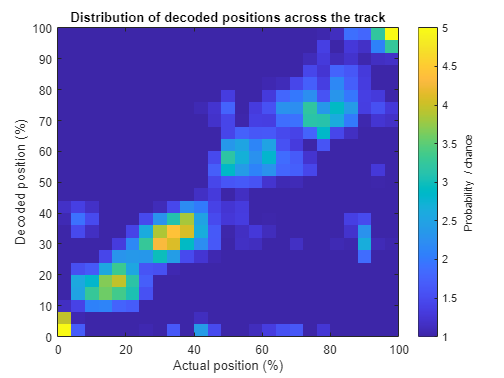

figure;
imagesc(PatDec.Xbincenters, PatDec.Xbincenters, Xdecmat);
set(gca,'Clim', [1 5], 'YDir', 'normal');
ylabel('Decoded position (%)')
xlabel('Actual position (%)')
title('Distribution of decoded positions across the track');
c = colorbar;
c.Label.String = 'Probability  / chance';